# Servomecanismos Proyecto Académico

*Isa y los Servotasticos*

## Parámetros

El eje fijo se deja en:

punto_fijo = [0; 0];

El centro del trébol estará ubicado en (se escogió arbitrariamente): 

centro_trebol = [25; 25];

 Con esto, necesitamos que los eslabones en máxima extensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2

radio_punto_max = 49.4621

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 30;
largo_eslabon_2 = 20;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max

radio_tolerancia = 0.5379

Se fijan los valores de a y b para que el trébol mida 15 cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trébol):

a_min = 1.332; % No cambiar 1.332
b_no_rot = 4.71; % No cambiar 4.71

Para ajustar la escala y rotación del trébol:

escala = 1; % default = 1
rotacion = 0; % default = 0
a_trebol = a_min * escala;
b_trebol = b_no_rot + rotacion;

## Puntas de los eslabones a partir de ángulos

syms theta_1;
syms theta_2;

La ubicación de las puntas de los eslabones estará dada por las siguientes expresiones:

articulacion_x(theta_1) = punto_fijo(1)+largo_eslabon_1*cos(theta_1)

$$a\_x(theta\_1) = 30\,\cos\left(\theta_{1}\right)$$

articulacion_y(theta_1) = punto_fijo(2)+largo_eslabon_1*sin(theta_1)

$$a\_y(theta\_1) = 30\,\sin\left(\theta_{1}\right)$$

herramienta_x(theta_1, theta_2) = articulacion_x+largo_eslabon_2*cos(theta_1+theta_2)

$$b\_x(theta\_1, theta\_2) = 20\,\cos\left(\theta_{1}+\theta_{2}\right)+30\,\cos\left(\theta_{1}\right)$$

herramienta_y(theta_1, theta_2) = articulacion_y+largo_eslabon_2*sin(theta_1+theta_2)

$$b\_y(theta\_1, theta\_2) = 20\,\sin\left(\theta_{1}+\theta_{2}\right)+30\,\sin\left(\theta_{1}\right)$$

## Ángulos a partir de posición de articulación y herramienta

theta_1_fn_a_x = finverse(articulacion_x) % en la función resultante theta_1 en realidad es articulacion_x

$$theta\_1\_fn\_a\_x(theta\_1) = \mathrm{acos}\left(\frac{\theta_{1}}{30}\right)$$

theta_1_fn_a_y = finverse(articulacion_y) % en la función resultante theta_1 en realidad es articulacion_y

$$theta\_1\_fn\_a\_y(theta\_1) = \mathrm{asin}\left(\frac{\theta_{1}}{30}\right)$$

theta_2_fn_b_x = finverse(herramienta_x, theta_2) % en la función resultante theta_2 en realidad es herramienta_x

$$theta\_2\_fn\_b\_x(theta\_1, theta\_2) = \mathrm{acos}\left(\frac{\theta_{2}}{20}-\frac{3\,\cos\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

theta_2_fn_b_y = finverse(herramienta_y, theta_2) % en la función resultante theta_2 en realidad es herramienta_y

$$theta\_2\_fn\_b\_y(theta\_1, theta\_2) = \mathrm{asin}\left(\frac{\theta_{2}}{20}-\frac{3\,\sin\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

### Ejemplo de encontrar ángulos a partir de la posición de articulación y herramienta

articulacion = [0; 30];
herramienta = [20; 30];
[theta_1_ab, theta_2_ab] = get_angs(articulacion, herramienta, theta_1_fn_a_x, theta_1_fn_a_y, theta_2_fn_b_x, theta_2_fn_b_y)

$$theta\_1\_ab = \frac{\pi }{2}$$

$$theta\_2\_ab = -\frac{\pi }{2}$$

articulacion = [articulacion_x(theta_1_ab); articulacion_y(theta_1_ab)];
herramienta = [herramienta_x(theta_1_ab, theta_2_ab); herramienta_y(theta_1_ab, theta_2_ab)];

### Gráfica

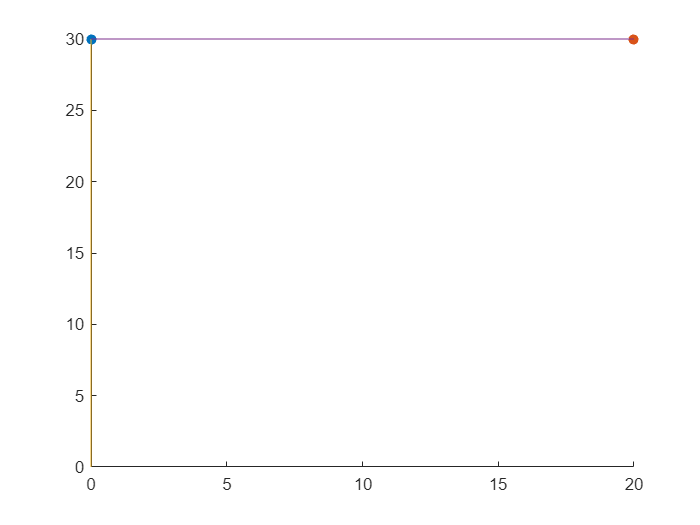

plot_triang(punto_fijo, articulacion, herramienta)

### Ejemplo de encontrar ángulos a partir de la posición de herramienta

herramienta = [20; 30];
[theta_1_b, theta_2_b] = get_angs_desde_herramienta(herramienta, theta_2_fn_b_x, theta_2_fn_b_y, herramienta_x, herramienta_y)

theta_1_b = 0

$$theta\_2\_b = 0$$

articulacion = [articulacion_x(theta_1_b); articulacion_y(theta_1_b)];
herramienta = [herramienta_x(theta_1_b, theta_2_b); herramienta_y(theta_1_b, theta_2_b)];

### Gráfica

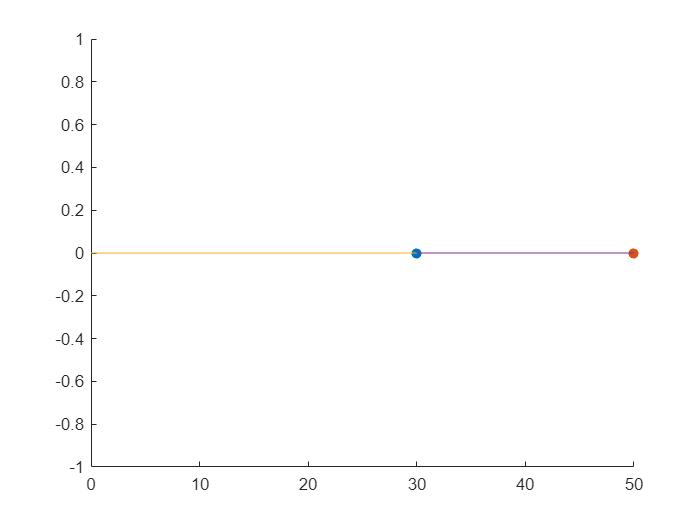

plot_triang(punto_fijo, articulacion, herramienta)

## trébol

### Definir la trayectoria

syms theta_trebol;
trebol_x(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

Si se quiere tener una mejor resolución en la discretización hay que cambiar la variable `intervalo_theta_trebol`. Entre más pequeño el intervalo mejor resolución.

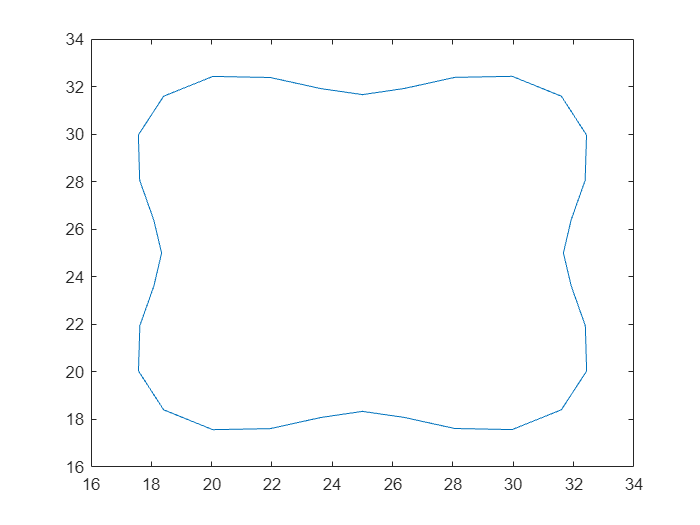

intervalo_theta_trebol = pi/16;
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

## Obtener ángulos para el recorrido

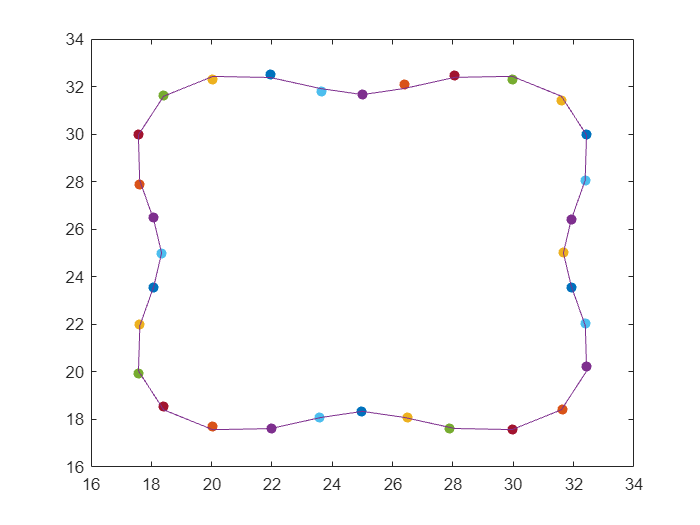

herramienta = [trebol_discretizado_x; trebol_discretizado_y];
[theta_1_trebol, theta_2_trebol] = get_angs_desde_herramienta_multi(herramienta, theta_2_fn_b_x, theta_2_fn_b_y, herramienta_x, herramienta_y);
articulacion_ans = [articulacion_x(theta_1_trebol); articulacion_y(theta_1_trebol)];
herramienta_ans = [herramienta_x(theta_1_trebol, theta_2_trebol); herramienta_y(theta_1_trebol, theta_2_trebol)];
plot_triang_con_trebol(punto_fijo, articulacion_ans, herramienta_ans, trebol_discretizado_x, trebol_discretizado_y)

[double(theta_1_trebol) double(theta_2_trebol)]

## Funciones

Esta función se usa para plotear el brazo.

function plot_triang(a, b, c)
    scatter(b(1), b(2), 'filled');
    hold on;
    scatter(c(1), c(2), 'filled');
    plot([a(1) b(1)], [a(2) b(2)])
    plot([b(1) c(1)], [b(2) c(2)])
    hold off;
end

Esta función se usa para plotear el brazo y el trébol. Se pueden comentar algunas líneas dependiendo de la información que se busca.

function plot_triang_con_trebol(a, b, c, trebol_discretizado_x, trebol_discretizado_y)
    for i = 1:length(b)
        %scatter(b(1,i), b(2,i), 'filled'); % articulacion
        hold on;
        scatter(c(1,i), c(2,i), 'filled'); % herramienta
        %plot([a(1) b(1,i)], [a(2) b(2,i)]) % eslabon 1. a(1) se deja
        %hardcoded porque solo hay un punto fijo
        %plot([b(1,i) c(1,i)], [b(2,i) c(2,i)]) % eslabon 2
        plot(trebol_discretizado_x, trebol_discretizado_y); % trébol
    end
    hold off;
end

Esta función se usa para obtener los ángulos si tenemos la posición deseada de la articulación y la herramienta.

function [theta_1, theta_2] = get_angs(articulacion, herramienta, theta_1_x, theta_1_y, theta_2_x, theta_2_y)
    theta_1_candidato = [theta_1_x(articulacion(1)); theta_1_y(articulacion(2))];
    theta_2_candidato = [theta_2_x(theta_1_candidato, herramienta(1)); theta_2_y(theta_1_candidato, herramienta(2))];
    if theta_1_candidato(1) == theta_1_candidato(2)
        theta_1 = mean(theta_1_candidato);
    end
    if theta_2_candidato(1) == theta_2_candidato(2)
        theta_2 = mean(theta_2_candidato);
    end
end

Esta función se usa para obtener los ángulos si tenemos la posición deseada de la herramienta. Los ángulos se consiguen por fuerza bruta, probablemente haya una mejor manera de realizar este cálculo.

Los valores hardcoded en los if son la tolerancia. Si se deja muy baja es probable que no se encuentre un valor para los ángulos. 

function [theta_1, theta_2] = get_angs_desde_herramienta(herramienta, theta_2_x, theta_2_y, herramienta_x, herramienta_y)
    for theta_1_candidato = 0:pi/256:2*pi % pi/256 es la resolucion de la busqueda
        theta_2_candidato_x = theta_2_x(theta_1_candidato, herramienta(1));
        theta_2_candidato_y = theta_2_y(theta_1_candidato, herramienta(2));
        if isreal(theta_2_candidato_x) && isreal(theta_2_candidato_y) 
            ans_x = herramienta_x(theta_1_candidato, theta_2_candidato_x);
            ans_y = herramienta_y(theta_1_candidato, theta_2_candidato_x);
            if (ans_x <= herramienta(1) + 0.5) && (ans_y <= herramienta(2) + 0.5) && (ans_x >= herramienta(1) - 0.5) && (ans_y >= herramienta(2) - 0.5)
                theta_1 = theta_1_candidato;
                theta_2 = theta_2_candidato_x;
                break
            end
            ans_x = herramienta_x(theta_1_candidato, theta_2_candidato_y);
            ans_y = herramienta_y(theta_1_candidato, theta_2_candidato_y);
            if (ans_x <= herramienta(1) + 0.5) && (ans_y <= herramienta(2) + 0.5) && (ans_x >= herramienta(1) - 0.5) && (ans_y >= herramienta(2) - 0.5)
                theta_1 = theta_1_candidato;
                theta_2 = theta_2_candidato_y;
                break
            end
        end
    end
end

Esta función se usa para llamar `get_angs_desde_herramienta` con varias posiciones deseadas.

function [theta_1, theta_2] = get_angs_desde_herramienta_multi(herramienta, theta_2_x, theta_2_y, herramienta_x, herramienta_y)
    theta_1 = [];
    theta_2 = [];
    for i = 1:length(herramienta)
        [theta_1_ans, theta_2_ans] = get_angs_desde_herramienta(herramienta(:,i), theta_2_x, theta_2_y, herramienta_x, herramienta_y);
        theta_1(end+1) = theta_1_ans;
        theta_2(end+1) = theta_2_ans;
    end
end